addpath("../helperFunctions/");
clearvars;

# Monopole Wave

### Initial Parameters

n = 3; spacing = 0.01;
f = 200; c = 343; omega = 2*pi*f;
mag = 10;
rho_k = omega/c;
S= [2;2;0];
[rho_s,the_s,phi_s] = my_cart2sph(S);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry) length(rx)];
rz = zeros(size(rx));
r = [rx;ry;rz];
R = 0.5; % region of interrest
N = ceil(exp(1)*rho_k*R/2);

## Monopole Sound Source

figure;
wave = monopoleWave(S,r,mag,rho_k,1);

## Harmonic Coefficients - Numerical Approximation


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


### Matlab

n = 1000;
a1 = 0;  a2 = 0;
b1 = pi; b2 = 2*pi;
Clm2 = zeros(N+1,2*N+1);


for l=0:N
    idl = l+1;
    for m=-l:l
        idm = m+idl;
        fun = @(the,phi) monopoleWaveSpherical(mag,rho_s,the_s,phi_s,R,the,phi,rho_k).*cYlm(l,m,the,phi)./sphbessel(l,rho_k*R);
        Clm2(idl,idm) = integral2(fun,a1,b1,a2,b2);
    end
end

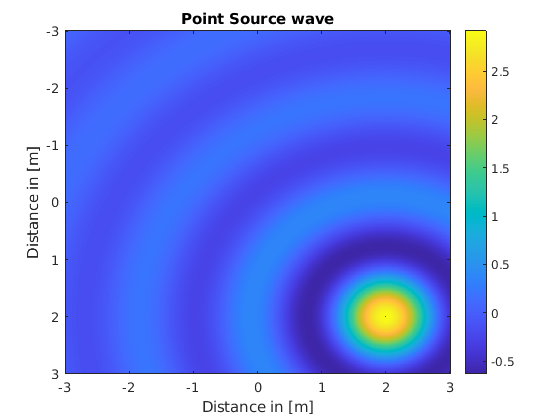

P2 = harmonics2pressure(Clm2,rho_k,r,sz);

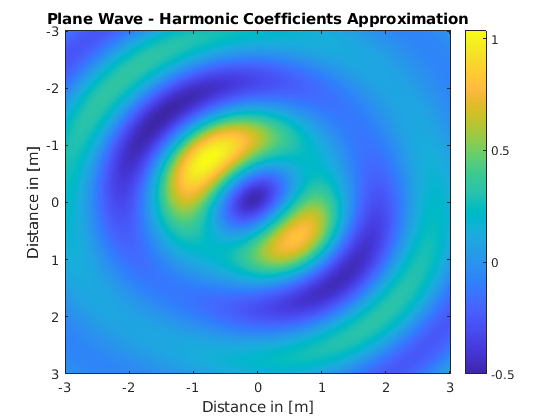

figure;
imagesc(r(1,:),r(2,:),imag(P2));
xlabel("Distance in [m]"); ylabel("Distance in [m]");
title("Plane Wave - Harmonic Coefficients Approximation");
colorbar;

### Compare

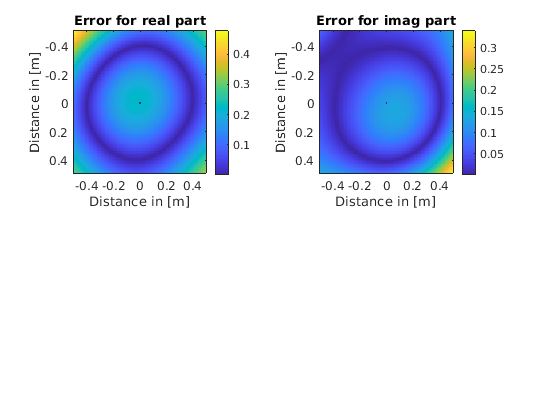

ans = "Max real error:  3.39e-01"

ans = "Max imag error:  4.77e-01"

ans = "Mean error: 8.24e-02"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);
cmpWaves(wave(interval1,interval2),P2(interval1,interval1),[r(1,interval1);r(2,interval2)],1);

### Guassian Sampling

waveFun = @(R,the,phi) monopoleWaveSpherical(mag,rho_s,the_s,phi_s,R,the,phi,rho_k);
[Clm,~] = harmonicCoefficients(R,rho_k,N,waveFun,n,wave,1);

### Evaluate

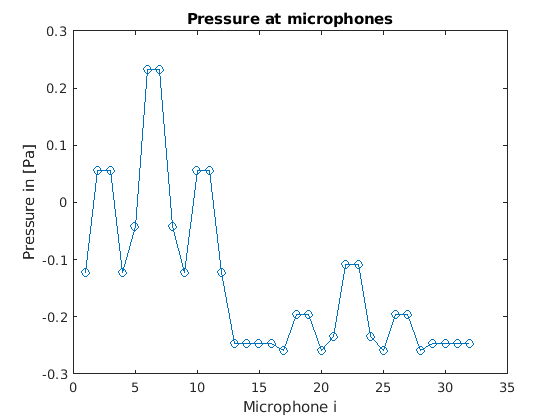

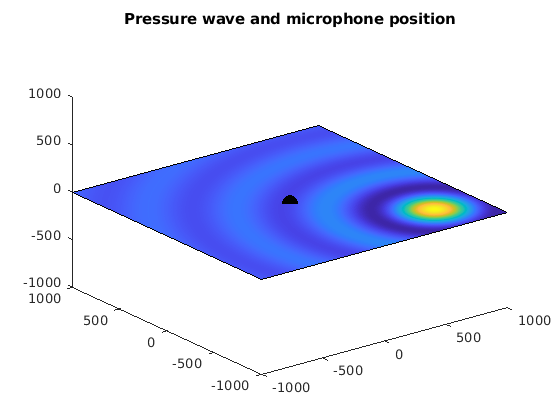

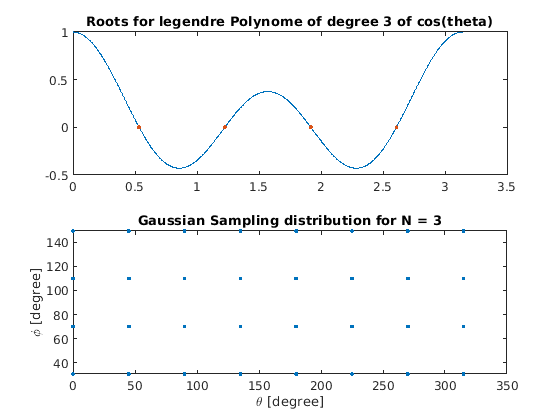

P = harmonics2pressure(Clm,rho_k,r,sz);

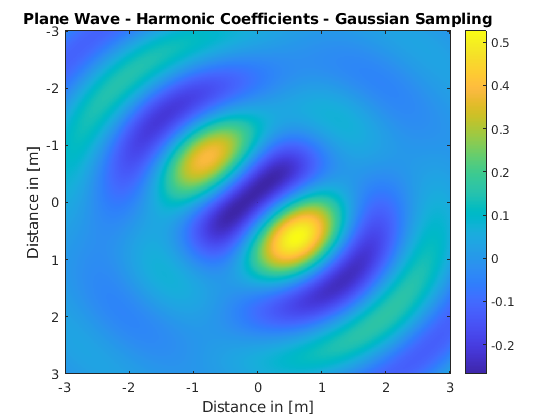

figure;
imagesc(r(1,:),r(2,:),imag(P));
xlabel("Distance in [m]"); ylabel("Distance in [m]");
title("Plane Wave - Harmonic Coefficients - Gaussian Sampling");
colorbar;

### Compare

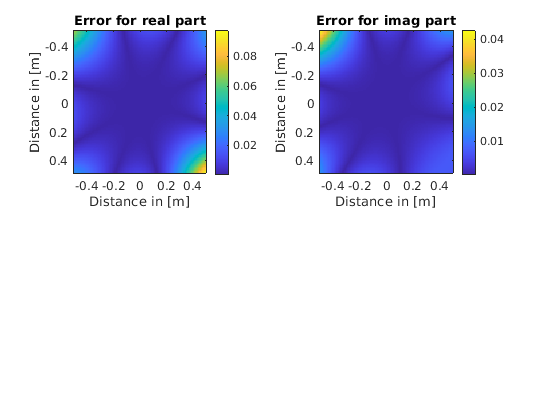

ans = "Max real error:  4.24e-02"

ans = "Max imag error:  9.71e-02"

ans = "Mean error: 5.15e-03"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);

cmpWaves(wave(interval1,interval2),P(interval1,interval1),[r(1,interval1);r(2,interval2)],1);